## **SIO 207A HW-6**

**Ruipu Ji**

% Initialization and default plot settings.
clear; clc; close all;

set(0, 'DefaultAxesFontSize', 10);
set(0, 'DefaultTextFontSize', 10);

set(0, 'DefaultTextInterpreter', 'latex');
set(0, 'DefaultLegendInterpreter', 'latex');
set(0, 'DefaultAxesTickLabelInterpreter', 'latex');


A. Using an equiripple FIR filter design algorithm, redesign the decimation filter with the new stopband frequency and a passband/stopband weighting ratio = 1. Plot *h*(*n*) (amplitude) and |*H*(*f*)| (dB). Use NFFT = 256. Compare the sidelobe attenuation and passband ripple (dB) of this new filter with the previous filter design.

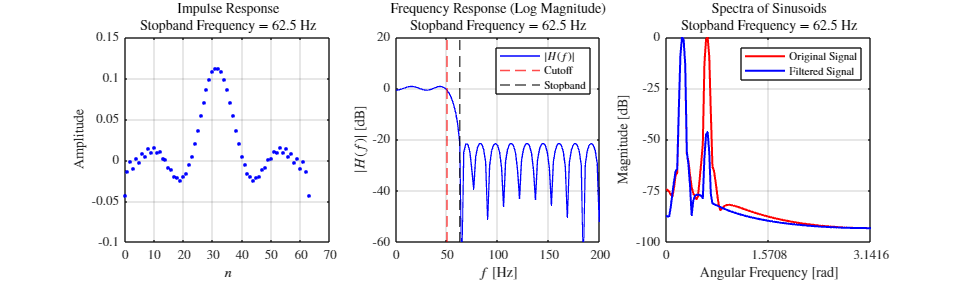

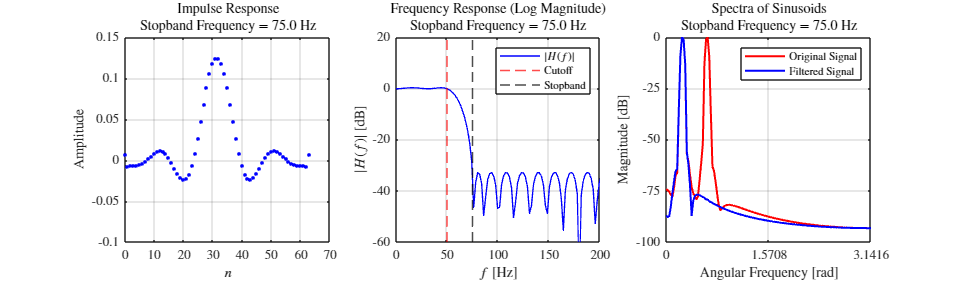

% Define parameters.
N = 64; % Number of coefficients.
fs = 1000; % Sampling frequency (Hz).
fc = 50; % Cutoff frequency (Hz).
f_stopband = [62.5 75]; % Stopband frequency (Hz).

% Define the signal x(t).
f2 = 40.5;
f3 = 100;
t = (0:1/fs:(fs-1)/fs)'; 
x = sin(2*pi*f2*t) + sin(2*pi*f3*t);

% Define the Kaiser-Bessel window (α = 2.5 or β = πα = 7.85).
NFFT = 256;
KaiserBesselWindow = kaiser(NFFT, 7.85);

% Define the frequency vector for spectra plot.
f = (0:1/NFFT:(NFFT-1)/NFFT)*2*pi;

% For two stop band frequencies:
for i = 1:size(f_stopband,2)
    % Design the FIR low pass filter.
    frequency = [0 fc/(fs/2) f_stopband(i)/(fs/2) 1];
    amplitude = [1 1 0 0];
    LPF = firpm(N-1, frequency, amplitude);

    % Calcualte the frequency response.
    [H,F] = freqz(LPF, 1, NFFT, fs);

    % Filter the signal.
    y = filtfilt(LPF, 1, x);
   
    x_windowed = x(1:NFFT).*KaiserBesselWindow;
    y_windowed = y(1:NFFT).*KaiserBesselWindow;
    
    % Calculate the 256-point FFT.
    X = fft(x_windowed, NFFT); 
    Y = fft(y_windowed, NFFT);
    
    % Calculate the amplitude in log magnitude.
    X_dB = 20*log10(abs(X));
    Y_dB = 20*log10(abs(Y));
    
    % Normalize the amplitude.
    X_dB = X_dB - max(X_dB);
    Y_dB = Y_dB - max(Y_dB);

    % Plot the result.
    figure('Position',[0 0 1200 350]);

    subplot(1,3,1); % Plot the impulse response (filter coefficients).
    hold on;
    scatter(0:N-1, LPF, 8, 'b', 'o', 'filled');
    grid on;
    box on;
    xlim([0 70]);
    xticks(0:10:70);
    ylim([-0.1 0.15]);
    yticks(-0.1:0.05:0.15);
    xlabel('$n$');
    ylabel('Amplitude');
    title(sprintf('Impulse Response\nStopband Frequency = %.1f Hz', f_stopband(i)));
    
    subplot(1,3,2); % Plot the frequency response (log magnitude).
    hold on;
    plot(F, 20*log10(abs(H)), 'b', 'LineWidth', 1);
    xline(fc, 'r--', 'LineWidth', 1);
    xline(f_stopband(i), 'k--', 'LineWidth', 1);
    grid on;
    box on;
    xlim([0 200]);
    xticks(0:50:200);
    ylim([-60 20]);
    yticks(-60:20:20);
    xlabel('$f$ [Hz]');
    ylabel('$|H(f)|$ [dB]');
    legend('$|H(f)|$', 'Cutoff', 'Stopband');
    title(sprintf('Frequency Response (Log Magnitude)\nStopband Frequency = %.1f Hz', f_stopband(i))); 

    subplot(1,3,3); % Spectra plot for the original and filtered signals.
    hold on;
    plot(f, X_dB, 'r', 'LineWidth', 1.5);
    plot(f, Y_dB, 'b', 'LineWidth', 1.5);
    grid on;
    box on;
    xlim([0 pi]);
    xticks(0:0.5*pi:pi);
    % xticklabels({'0', '\pi/2', '\pi'});
    ylim([-100 0]);
    yticks(-100:25:0);
    xlabel('Angular Frequency [rad]');
    ylabel('Magnitude [dB]');
    legend('Original Signal', 'Filtered Signal', 'Location', 'northeast');
    title(sprintf('Spectra of Sinusoids\nStopband Frequency = %.1f Hz', f_stopband(i)));          
end

Figure A1. Comparison for impulse response, frequency response and spectra on two different stopband frequencies.

With the same cutoff frequency (50 Hz) and weight ratio (1.0), the passband ripples decreases (becomes smoother) as the transition width increases. For both the spectra plots using two filters, two peaks with the same magnitude are observed in the spectra of the original signal, which represent the two frequency components (40.5 Hz and 100 Hz) in the original signal. However, a lower peak corresponding to the 100 Hz frequency component.is observed when using the narrow transition width (12.5 Hz), while no other peaks are observed when using the wide transition width (25 Hz). The filter with a wider transtion width performs better in removing the high frequency component.

B. Next, normalize the impulse response so that max |*h*(*n*)| =1. Plot *h*(*n*) (amplitude) and |*H*(*f*)| (dB). Use NFFT = 256. Also, plot the zero locations of *H*(*z*).

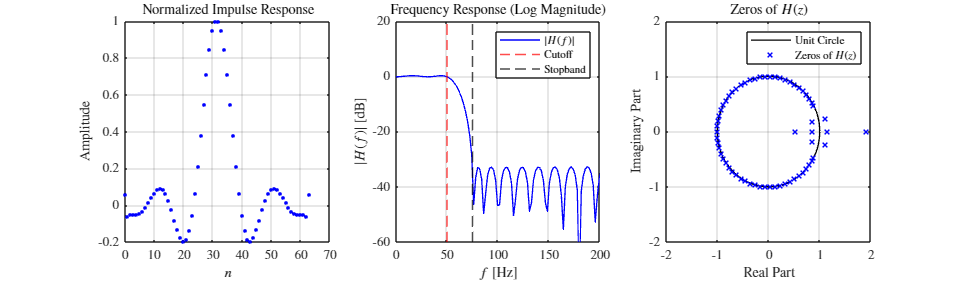

% Design the FIR low pass filter.
frequency = [0 fc/(fs/2) f_stopband(2)/(fs/2) 1];
amplitude = [1 1 0 0];
LPF = firpm(N-1, frequency, amplitude);

% Normalize the impulse response.
LPF_normalized = LPF / max(abs(LPF));

% Calcualte the frequency response.
[H,F] = freqz(LPF, 1, NFFT, fs);

% Calculate zero locations.
H_zeros = roots(LPF);

% Plot the result.
figure('Position',[0 0 1200 350]);

subplot(1,3,1); % Plot the impulse response (filter coefficients).
hold on;
scatter(0:N-1, LPF_normalized, 8, 'b', 'o', 'filled');
grid on;
box on;
xlim([0 70]);
xticks(0:10:70);
ylim([-0.2 1]);
yticks(-0.2:0.2:1);
xlabel('$n$');
ylabel('Amplitude');
title('Normalized Impulse Response');

subplot(1,3,2); % Plot the frequency response (log magnitude).
hold on;
plot(F, 20*log10(abs(H)), 'b', 'LineWidth', 1);
xline(fc, 'r--', 'LineWidth', 1);
xline(f_stopband(2), 'k--', 'LineWidth', 1);
grid on;
box on;
xlim([0 200]);
xticks(0:50:200);
ylim([-60 20]);
yticks(-60:20:20);
xlabel('$f$ [Hz]');
ylabel('$|H(f)|$ [dB]');
legend('$|H(f)|$', 'Cutoff', 'Stopband');
title('Frequency Response (Log Magnitude)');

subplot(1,3,3); % Plot zero locations of H(z).
hold on;

% Plot the unit circle.
theta = linspace(0, 2*pi, 100);
plot(cos(theta), sin(theta), 'k', 'LineWidth', 1);

% Plot the zero locations.
plot(real(H_zeros), imag(H_zeros), 'x', 'Color', 'b', 'MarkerSize', 5, 'LineWidth', 1);
grid on;
box on;
xlim([-2 2]);
xticks(-2:1:2);
ylim([-2 2]);
yticks(-2:1:2);
xlabel('Real Part');
ylabel('Imaginary Part');
title('Zeros of $H(z)$');
legend('Unit Circle', 'Zeros of $H(z)$', 'Location', 'northeast');

Figure B1. Noramlaized impulse response, frequency response and zero locations for the filter with the larger transition width.

C & D. Quantization.

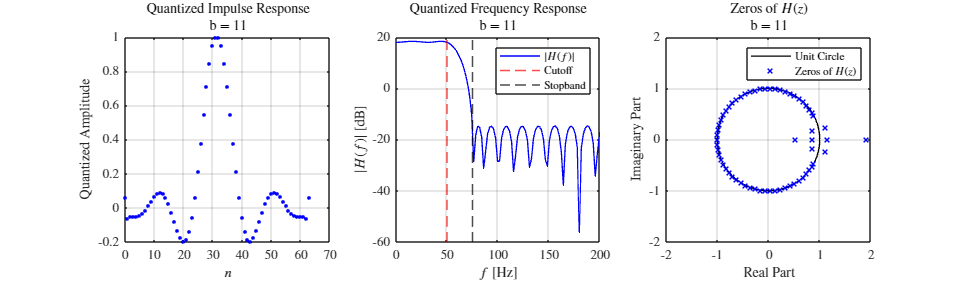

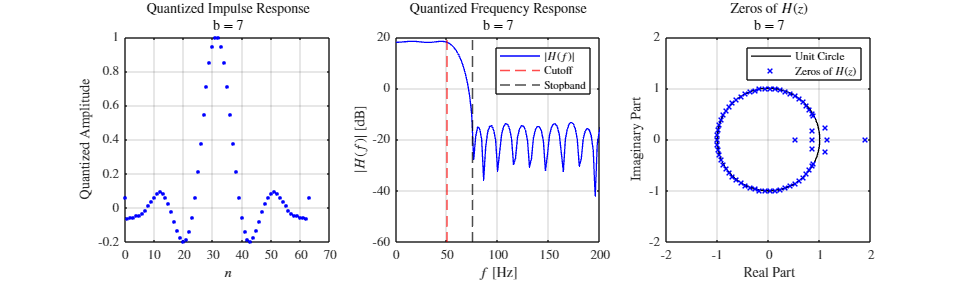

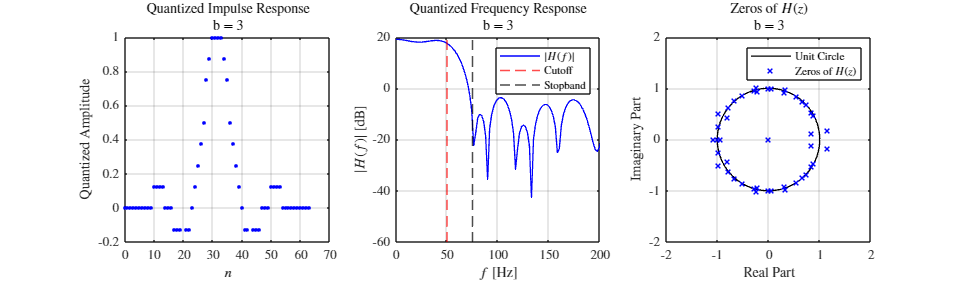

% Define the fractional bit values.
b = [11, 7, 3];

% Loop over the different fractional bit values:
for i = 1:size(b,2)
    % Calculate the quantization step size.
    QuantizationStep = 2^(-b(i));
    
    % Quantize the impulse response.
    LPF_quantized = round(LPF_normalized / QuantizationStep) * QuantizationStep;

    % Calculate the frequency response of the quantized filter.
    [H_quantized, F_quantized] = freqz(LPF_quantized, 1, NFFT, fs);

    % Calculate zero locations.
    H_quantized_zeros = roots(LPF_quantized);

    % Plot the result.
    figure('Position',[0 0 1200 350]);
    
    subplot(1,3,1); % Plot the quantized impulse response.
    hold on;
    scatter(0:N-1, LPF_quantized, 8, 'b', 'o', 'filled');
    grid on;
    box on;
    xlim([0 70]);
    xticks(0:10:70);
    ylim([-0.2 1]);
    yticks(-0.2:0.2:1);
    xlabel('$n$');
    ylabel('Quantized Amplitude');
    title(sprintf('Quantized Impulse Response\nb = %d', b(i)));
    
    subplot(1,3,2); % Plot the quantized frequency response (log magnitude).
    hold on;
    plot(F, 20*log10(abs(H_quantized)), 'b', 'LineWidth', 1);
    xline(fc, 'r--', 'LineWidth', 1);
    xline(f_stopband(2), 'k--', 'LineWidth', 1);
    grid on;
    box on;
    xlim([0 200]);
    xticks(0:50:200);
    ylim([-60 20]);
    yticks(-60:20:20);
    xlabel('$f$ [Hz]');
    ylabel('$|H(f)|$ [dB]');
    legend('$|H(f)|$', 'Cutoff', 'Stopband');
    title(sprintf('Quantized Frequency Response\nb = %d', b(i)));
    
    subplot(1,3,3); % Plot zero locations of H(z).
    hold on;
    
    % Plot the unit circle.
    theta = linspace(0, 2*pi, 100);
    plot(cos(theta), sin(theta), 'k', 'LineWidth', 1);
    
    % Plot the zero locations.
    plot(real(H_quantized_zeros), imag(H_quantized_zeros), 'x', 'Color', 'b', 'MarkerSize', 5, 'LineWidth', 1);
    grid on;
    box on;
    xlim([-2 2]);
    xticks(-2:1:2);
    ylim([-2 2]);
    yticks(-2:1:2);
    xlabel('Real Part');
    ylabel('Imaginary Part');
    title(sprintf('Zeros of $H(z)$\nb = %d', b(i)));
    legend('Unit Circle', 'Zeros of $H(z)$', 'Location', 'northeast');
end

Figure D1. Quantized impulse response, frequency response and zero locations for different fractional bit values.